# Filtros

## Importar datos

Importar "S9....mat" de Utils4SP

load("../../Utils4SP/Datasets/S9_Filtros.mat")

%Preproc
atmosfera(:,["Pres_kpa" "Temp_C" "Hum_perc"])=fillmissing(atmosfera(:,["Pres_kpa" "Temp_C" "Hum_perc"]),"linear");

## Promedio móvil

- Aplicar promedio móvil a todos los campos de atmósfera

- Comparar series de tiempo antes y después

- Comparar el contenido espectral antes y después del filtro

- Hacer un chart de dispersión y hacer nuevamente un ajuste. Comparar la calidad del ajuste respecto a la práctica de S5.

%Promedio móvil 
atmos_movMean_3=movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},3);
atmos_movMean_100=movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},100);
atmos_movMean_1000=movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},1000);
atmos_movMean_10000=movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},10000);

%Visualizar temperatura sin filtro y con filtro
figure
plot(atmosfera.DateTime,[ ...
    atmosfera.Temp_C ...
    atmos_movMean_3(:,2) ...
    atmos_movMean_100(:,2) ...
    atmos_movMean_1000(:,2)],'LineWidth',2)
xlim([datetime(2021,05,19) datetime(2021,05,20)])
legend("Original","Orden 3","Orden 100","Orden 1000" )
ylabel("Temperatura °C")
title("Temperatura en mi casa")
grid on

%Contenido espectral
N=numel(atmosfera.Temp_C);
[Pxx,f]=periodogram([ ...
    atmosfera.Temp_C ...
    atmos_movMean_3(:,2) ...
    atmos_movMean_100(:,2) ...
    atmos_movMean_1000(:,2)],flattopwin(N),N*10,1/5);

%Visualización de contenido espectral
figure
plot(f,pow2db(Pxx))
legend("Original","Orden 3","Orden 100","Orden 1000" )
title("Contenido espectral de la temperatura")
ylabel("PSD dB")
xlabel("Frecuencia [Hz]")
grid on

%Ajuste
[fit_line_nofil,gof]=fit(atmosfera.Temp_C,atmosfera.Hum_perc,'poly2')
[fit_line_fil,gof]=fit(atmos_movMean_10000(:,2),atmos_movMean_10000(:,3),'poly2')


%Dispersión filtrada Hum vs temp
figure
%Original
scatter(atmosfera.Temp_C,atmosfera.Hum_perc)

fit_line_nofil =      Linear model Poly2:
     fit_line_nofil(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =     0.05092  (0.05045, 0.05139)
       p2 =      -5.293  (-5.319, -5.266)
       p3 =       142.2  (141.8, 142.5)

gof = struct with fields:
           sse: 1.4789e+07
       rsquare: 0.7424
           dfe: 137519
    adjrsquare: 0.7424
          rmse: 10.3702


hold on

fit_line_fil =      Linear model Poly2:
     fit_line_fil(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =     0.02578  (0.02056, 0.03101)
       p2 =      -3.882  (-4.122, -3.642)
       p3 =       124.9  (122.1, 127.6)

gof = struct with fields:
           sse: 1.1565e+07
       rsquare: 0.4629
           dfe: 137519
    adjrsquare: 0.4629
          rmse: 9.1704


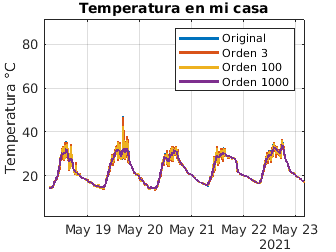

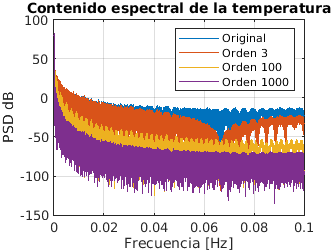

plot(fit_line_nofil)
%Filtro orden 1000
scatter(atmos_movMean_10000(:,2),atmos_movMean_10000(:,3))
plot(fit_line_fil)
hold off
xlim([10 50])
ylim([0 100])
xlabel("Tempratura [°C]")
ylabel("Humedad [%]")
grid on
title("Humedad vs temperatura")

legend("Original","Ajuste original","Promedio móvil","Ajuste promedio movil")
%El promeido móvil no fue bueno para quitar las variaciones en el chart de
%dispersión de humedad contra temperatura.


## Detrend

Hacer detrend a las componentes x & y del campo magnético de Cassini con las siguientes técnicas:

- Restando promedio móvil

- Ajustando un polinomio

- Usando detrend

Aplicar el espectrograma a la magnitud de Cassini antes y después del detrend. Observar por qué es importante quitar las bajas frecuencias (Incluido el DC).

## No lineales

Contexto: Los datos de RVB son producto de un sensor altamente inestable y ruidoso.

Hacer la reconstrucción facial de los datos de RVB:

- Remover NaN's

- Usar un filtro no lineal para quitar la mayor cantidad de ruido

- Usar promedio móvil para dar el toque final